# Instructions to run this DEMO:  A slider crank mechanism

### Release of MATLAB required to run this DEMO:

- This demo has been run and tested in R2020b 

- The demo should also run in R2021a - but has NOT been tested in that Release.

### Products needed to run this example:

- MATLAB

- Simulink

- Simscape

- Simscape multibody

# Example II

Consider the slider crank mechanism shown in **Figure 1** below. For the configuration shown in **Figure 1a**, determine:

- $v_B$ the velocity of piston $B$

- $\omega_{\textrm{AB}}$ the angular velocity of rod$\textrm{AB}$

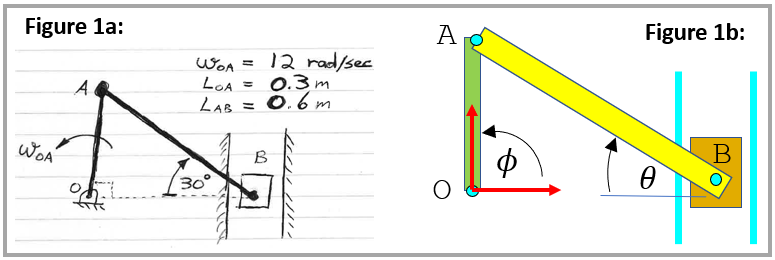

Let's define some MATLAB variables that characterise the system shown in **Figure 1a **and** Figure 1b:**

phi_rad             = deg2rad(90);  % (rad)
theta_rad           = deg2rad(30);  % (rad)
phi_dot_rad_per_sec = 12;           % (rad/sec)
omega_OA            = phi_dot_rad_per_sec;

L_OA       = 0.3;                   % (m)
L_AB       = 0.6;                   % (m) 
L_OB       = L_AB * cos(theta_rad); % (m)

##  Brain Analysis - your turn

Perform your analysis with Pen and paper.  What did you compute for:

- $v_B$ and $\omega_{\textrm{AB}}$

##   Hand Computation Analysis - one approach

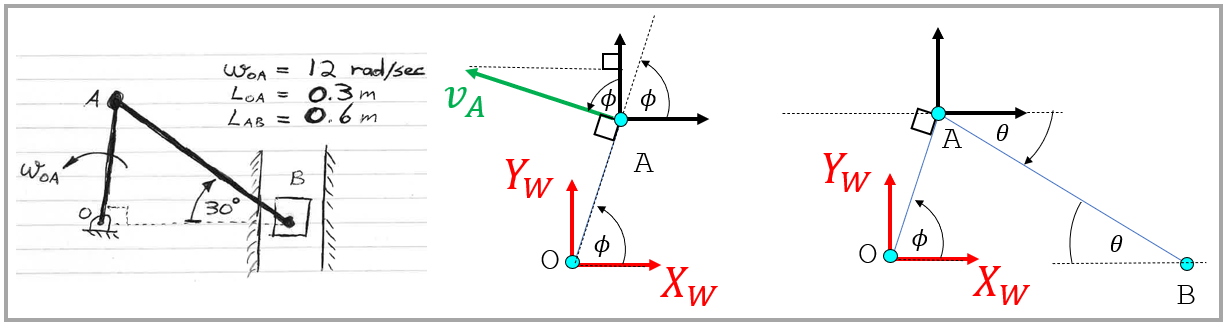

The velocity of point A can be computed as $v_A =\omega_{\textrm{OA}} \;\times r_{A\left|O\right.} \;$  and we can decompose it into its components in the world {W - frame}

vA_mag = omega_OA * L_OA;
vA_vec = [ -1 * vA_mag * sin(phi_rad);
                vA_mag * cos(phi_rad)  ]

vA_vec =    -3.6000
    0.0000


We can compute the velocity of point $B$ as:

- 
$$v_B \;\;=\;v_A \;\;\;\;+\;\;\;\;\omega_{\textrm{AB}} \times r_{B\left|A\right.} \;\;\;\;=\;\;\left\lbrack \begin{array}{c}
v_{\textrm{AX}} \\
v_{\textrm{AY}} 
\end{array}\right\rbrack \;\;\;+\;\;\;\left|\left\lbrack \begin{array}{ccc}
i & j & k\\
0 & 0 & \omega_{\textrm{AB}} \\
L_{\textrm{AB}} \ldotp \cos \left(\theta \right) & {-L}_{\textrm{AB}} \ldotp \sin \left(\theta \right) & 0
\end{array}\right\rbrack \right|\;\;=\;\;\left\lbrack \begin{array}{c}
v_{\textrm{AX}} \;\;+\;L_{\textrm{AB}} \ldotp \sin \left(\theta \right)\ldotp \omega_{\textrm{AB}} \\
v_{\textrm{AY}} \;\;+\;L_{\textrm{AB}} \ldotp \cos \left(\theta \right)\ldotp \omega_{\textrm{AB}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
v_{\textrm{BY}} 
\end{array}\right\rbrack$$


The derivative of the position constraint $x_B =L_3$  means that $v_{\textrm{BX}} =0$.  Which we can then use to write:

- 
$$\omega_{\textrm{AB}} \;\;\;\;=\frac{{-1\ldotp \;v}_{\textrm{AX}} }{\;L_{\textrm{AB}} \ldotp \sin \left(\theta \right)}\;\;\;$$


my_sol_omega_AB = -1*vA_vec(1) / (L_AB * sin(theta_rad));

And we can now solve for $v_{\textrm{BY}}$ using:

- 
$${v_{\textrm{BY}\;\;=\;\;\;} v}_{\textrm{AY}} \;\;+\;L_{\textrm{AB}} \ldotp \cos \left(\theta \right)\ldotp \omega_{\textrm{AB}}$$


my_sol_vBY  =  vA_vec(2)   +   L_AB*cos(theta_rad)*my_sol_omega_AB;

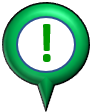** SUMMARY of results: **   We were asked to compute the following:

- $v_B$ the velocity of piston $B$

- $\omega_{\textrm{AB}}$ the angular velocity of rod$\textrm{AB}$

my_sol_omega_AB

my_sol_omega_AB = 12.0000

my_sol_vBY

my_sol_vBY = 6.2354

##  Compare against Simulink

Let's check our results by exploring a Simulink model.  Click on the button below to open the model:

  open_system("bh_example_02_crank.slx")

When the Simulink model appears, click the Run button - this will simulate the model for 0.7 seconds

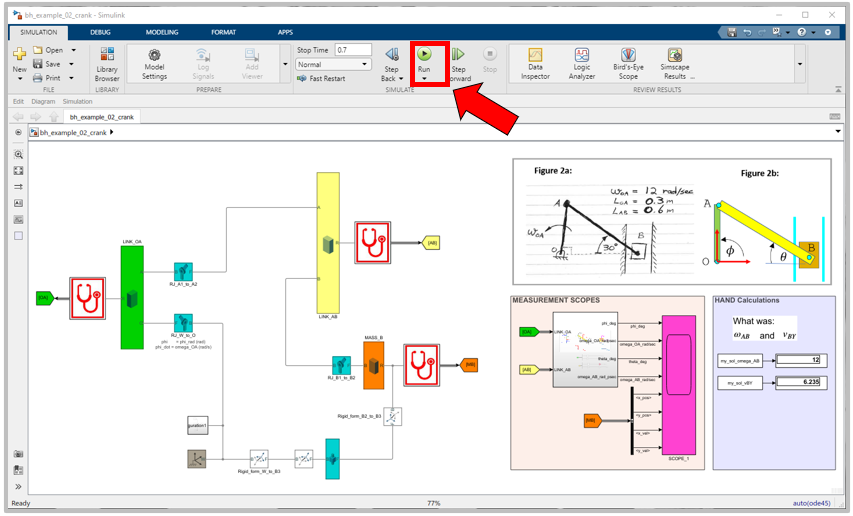

 

- Explore the 2 PINK SCOPE blocks and inspect the time series of the various angles and positions .

- when you zoom in around the $t=0\;\textrm{seconds}$ region in the SCOPES, do you see values for $v_B$ and $\omega_{\textrm{AB}}$ that are similar to your hand calculations ?

When you run the simulation you also get to see the mechanism animate for the 0.7 seconds of the simulation - note how the range of angular motion for rod $\textrm{OA}$ is constrained.  Let's expolore that constraint more in the next section.

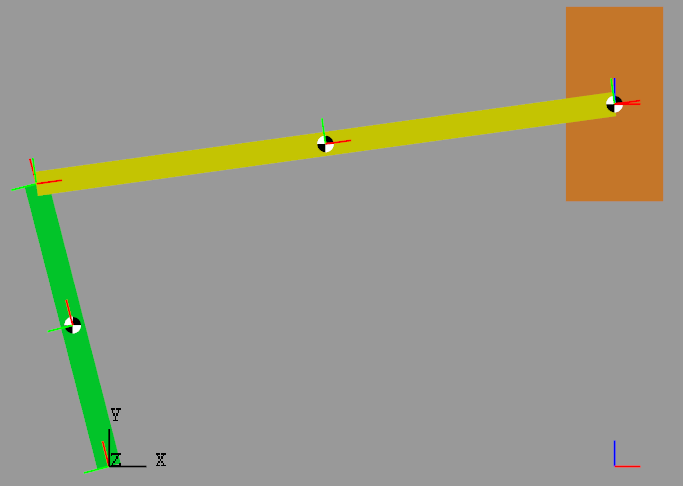

# Exploring the kinematic constraints

Consider the slider crank positioned in an ***arbitrary*** configuration as shown below:

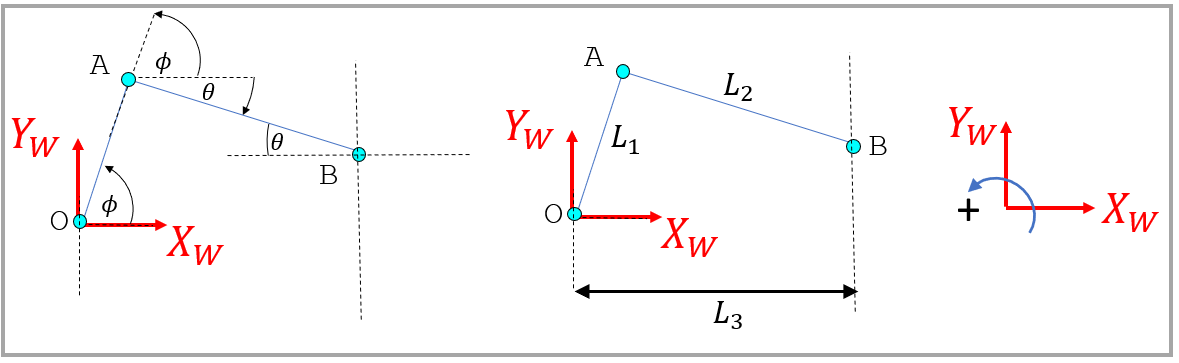

### Part 1 -    the  $x_B =L_3$  constraint

Let's write out the vector expression for the position of point $B$:

- 
$$P_B \;=P_A \;\;+\;P_{B\left|A\right.} \;\;=\;\;\left\lbrack \begin{array}{c}
L_1 \ldotp \cos \left(\phi \right)\\
L_1 \ldotp \sin \left(\phi \right)
\end{array}\right\rbrack \;+\;\left\lbrack \begin{array}{c}
L_2 \ldotp \cos \left(\theta \right)\\
-L_2 \ldotp \sin \left(\theta \right)
\end{array}\right\rbrack \;\;=\;\;\left\lbrack \begin{array}{c}
L_1 \ldotp \cos \left(\phi \right)\;\;+\;L_2 \ldotp \cos \left(\theta \right)\;\\
L_1 \ldotp \sin \left(\phi \right)\;\;-\;L_2 \ldotp \sin \left(\theta \right)\;
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_B \\
y_B 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
L_3 \\
y_B 
\end{array}\right\rbrack$$


So from our constraint $x_B =L_3$ we could write:

- $\cos \left(\theta \right)\;\;=\;\;\;\frac{{L_3 \;\;\;-\;\;\;L}_1 \ldotp \cos \left(\phi \right)}{L_2 }\;\;$and we could use the inverse cosine function to compute $\theta$ for the interval $\theta \;\epsilon \;\left\lbrack 0,\;\pi \;\right\rbrack$. 

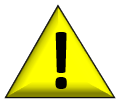When you look at the above expression, you can see that in order for us to have a "VALID" machine, we need the following condition to be true:

- $\left|\frac{L_3 -L_1 \ldotp \cos \left(\phi \right)}{L_2 }\right|\le 1$          because          $-1\le \;\;\cos \left(\textrm{some}\;\textrm{angle}\right)\;\;\le 1$

- If the above condition is NOT satisfied then we know that the mechanism canNOT be placed in that specific configuration

Since $\cos \left(\theta \right)$ is an EVEN function we also have a 2nd solution:

- $\theta_1 \;\;=\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{acos}\left(\;\;\;\frac{{L_3 \;\;\;-\;\;\;L}_1 \ldotp \cos \left(\phi \right)}{L_2 }\;\;\right)$   for    $\theta_1 \;\;\;\epsilon \;\;\;\left\lbrack 0,\;\pi \;\right\rbrack$.

- $\theta_2 \;\;=\;\;-1\;\ldotp \;\textrm{acos}\left(\;\;\;\frac{{L_3 \;\;\;-\;\;\;L}_1 \ldotp \cos \left(\phi \right)}{L_2 }\;\;\right)$   for    $\theta_2 \;\;\;\epsilon \;\;\;\left\lbrack -\pi ,0\;\right\rbrack$.

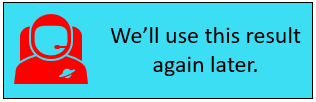

### Part 2 -    the  ${\dot{x} }_B =0$  constraint

We can also extract some useful results by considering the DERIVATIVE of the $x_B =L_3$ constraint, ie:

- 
$${\dot{x} }_B \;\;=\;\;0\;\;\;=\;\;-L_1 \ldotp \dot{\phi \ldotp } \;\sin \left(\phi \right)\;\;+\;\;-L_2 \ldotp \dot{\theta} \ldotp \sin \left(\theta \right)$$


Which we can rearrange to give :

- 
$$\dot{\theta} \;\;=\;\;\frac{L_1 \ldotp \dot{\phi \ldotp } \;\sin \left(\phi \right)}{-L_2 \ldotp \sin \left(\theta \right)}\;\;$$
    

If we stick with the Right Hand Rule convention for defining positive rotations relative to an inertial WORLD frame, we see that our generalised co-ordinate $\theta$ is positive in the NEGATIVE world sense (what a horrible phrase !).  To transform $\theta$ and $\dot{\theta}$ into quantities measured by the Right Hand Rule, we simply need to multiple by $-1$, ie:

- 
$$\omega_{\textrm{AB}\;\;} =\;\;\;\;-1\;\ldotp \dot{\theta}$$


### 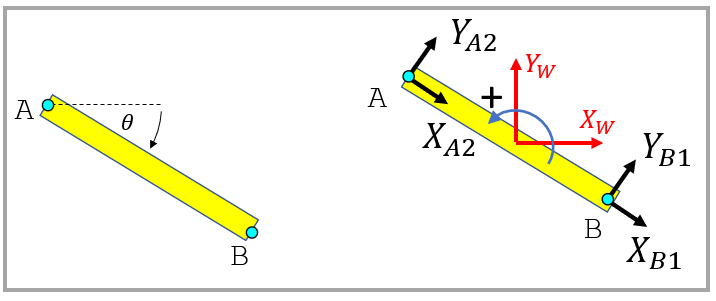

And finally, let's look for an expression for ${\dot{y} }_B$.   Recall that:

- 
$$P_B \;=P_A \;\;+\;P_{B\left|A\right.} \;\;=\;\;\left\lbrack \begin{array}{c}
L_1 \ldotp \cos \left(\phi \right)\\
L_1 \ldotp \sin \left(\phi \right)
\end{array}\right\rbrack \;+\;\left\lbrack \begin{array}{c}
L_2 \ldotp \cos \left(\theta \right)\\
-L_2 \ldotp \sin \left(\theta \right)
\end{array}\right\rbrack \;\;=\;\;\left\lbrack \begin{array}{c}
L_1 \ldotp \cos \left(\phi \right)\;\;+\;L_2 \ldotp \cos \left(\theta \right)\;\\
L_1 \ldotp \sin \left(\phi \right)\;\;-\;L_2 \ldotp \sin \left(\theta \right)\;
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_B \\
y_B 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
L_3 \\
y_B 
\end{array}\right\rbrack$$


therefore we have:

- 
$${\dot{y} }_B =\dot{\phi} \ldotp L_1 \ldotp \cos \left(\phi \right)\;\;-\;\;\dot{\theta} \ldotp L_2 \ldotp \cos \left(\theta \right)$$


### Part 3 -    Crunching the numbers

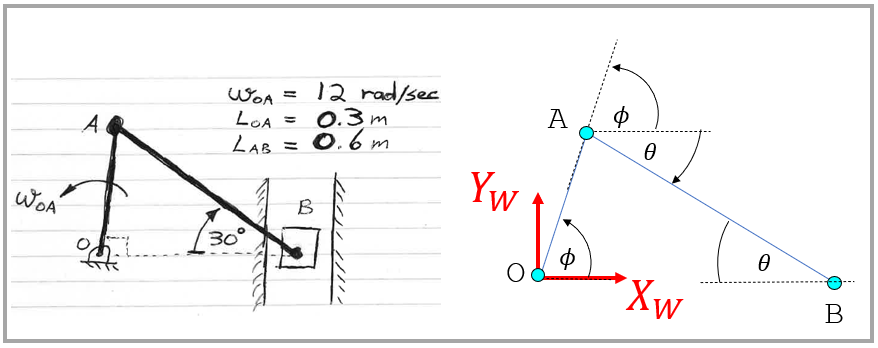

In the previous section we established the following:

- 
$$\theta \;\;\;=\;\;\;\;\mp \;\;\;\;\textrm{acos}\left(\;\;\;\frac{{L_3 \;\;\;-\;\;\;L}_1 \ldotp \cos \left(\phi \right)}{L_2 }\;\;\right)$$


- 
$$\omega_{\textrm{AB}\;\;} =\;\;\;\;-1\;\;\ldotp \;\frac{L_1 \ldotp \dot{\phi \ldotp } \;\sin \left(\phi \right)}{-L_2 \ldotp \sin \left(\theta \right)}$$


- 
$${\dot{y} }_B =\dot{\phi} \ldotp L_1 \ldotp \cos \left(\phi \right)\;\;-\;\;\dot{\theta} \ldotp L_2 \ldotp \cos \left(\theta \right)$$


Let's plug some numbers into these derived quantities:

L1           = L_OA; % (m)
L2           = L_AB; % (m) 
L3           = L_OB; % (m)

my_phi       = phi_rad;   % (rad)
my_phi_dot   = omega_OA;  % (rad/sec)

For our system(see** Figure 1a** above) we know that $\theta$ is positive when $\phi ={90}^{\circ }$

tmp_val      = (L3 - L1*cos(my_phi)) / L2;
my_theta_val =     acos(  tmp_val   );

So what value for $\theta$ could we have ?

my_theta_val_degs = rad2deg(my_theta_val)

my_theta_val_degs = 30.0000

my_theta_dot_val  = L1 * my_phi_dot * sin(my_phi) ./ (-1*L2* sin(my_theta_val));

So what value of $\omega_{\textrm{AB}\;\;}$could we have ?

my_omega_AB       = -1 * my_theta_dot_val

my_omega_AB = 12.0000

So what value of ${\dot{y} }_B$ could we have ?

my_yb_dot         = my_phi_dot * L1 .* cos(my_phi)   -   my_theta_dot_val * L2 .* cos(my_theta_val)

my_yb_dot = 6.2354